%simulating gating variables using Boltzmann function

%thermal energy at 300K
kT = 1.38e-23 * 300

kT = 4.1400e-21


%scaling factor for sharpness
w = kT*1e19

w = 0.0414


%charge-related term (z*e)
ze = 5*kT*1e19

ze = 0.2070


%voltage range (unitless)
E = 150:1:300

E =    150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175   176   177   178   179   180   181   182   183   184   185   186   187   188   189   190   191   192   193   194   195   196   197   198   199



%sigmoid-shaped channel open probability
po_fn =  1./(1+exp(w-ze.*E)./(kT))

po_fn =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0011    0.0013    0.0017    0.0020    0.0025    0.0031


%conductance curve parameters

%curve steepness
K = 15

K = 15

%half-activation voltage
Ehalf = -56

Ehalf = -56


%voltage range in mV
E = -70:0.001:-40

E =   -70.0000  -69.9990  -69.9980  -69.9970  -69.9960  -69.9950  -69.9940  -69.9930  -69.9920  -69.9910  -69.9900  -69.9890  -69.9880  -69.9870  -69.9860  -69.9850  -69.9840  -69.9830  -69.9820  -69.9810  -69.9800  -69.9790  -69.9780  -69.9770  -69.9760  -69.9750  -69.9740  -69.9730  -69.9720  -69.9710  -69.9700  -69.9690  -69.9680  -69.9670  -69.9660  -69.9650  -69.9640  -69.9630  -69.9620  -69.9610  -69.9600  -69.9590  -69.9580  -69.9570  -69.9560  -69.9550  -69.9540  -69.9530  -69.9520  -69.9510


%gating function
g_fn =  1./(1+exp(Ehalf-E)./(K))

g_fn =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


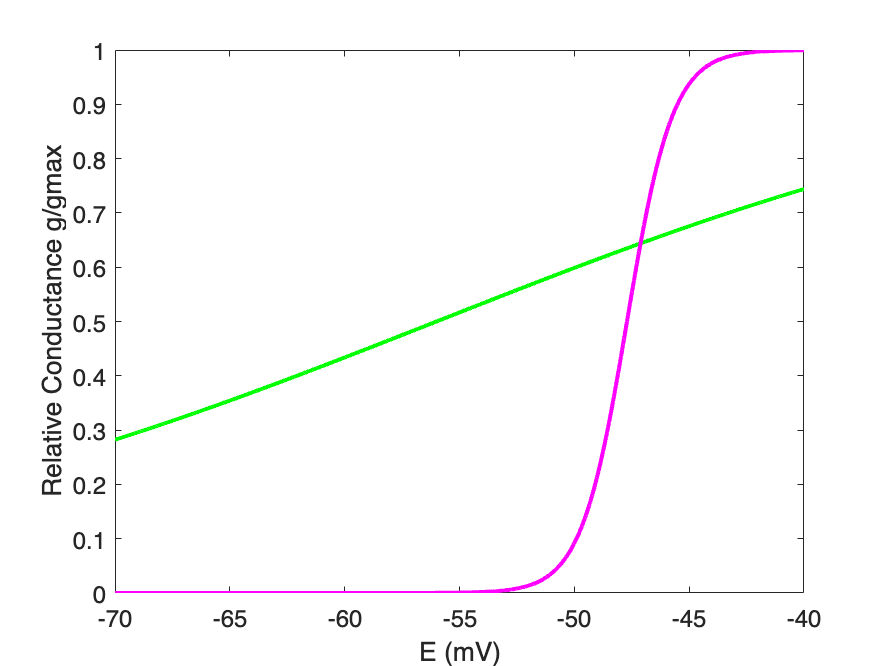


%plotting
figure(1)
hold off %clear plot
box on

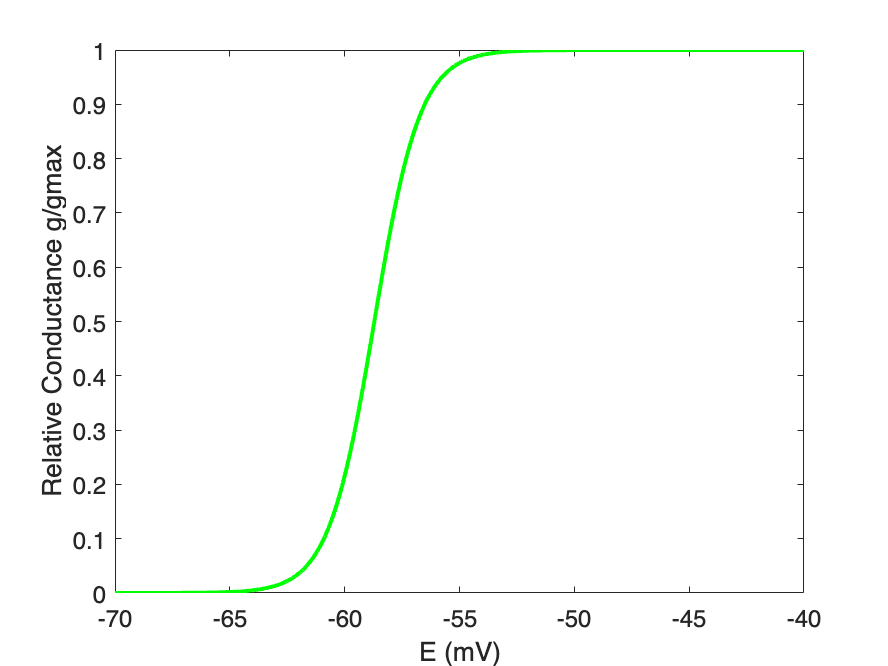

xP = E; yP = g_fn; %store x and y
plot(xP,yP,'g','linewidth',2) %green line
xlabel('E (mV)')
ylabel('Relative Conductance g/gmax')
set(gca,'fontsize',12)

%second gating curve with new Ehalf

%same K, new Ehalf
K = 15

K = 15

Ehalf = -45

Ehalf = -45


%same range
E = -70:0.001:-40

E =   -70.0000  -69.9990  -69.9980  -69.9970  -69.9960  -69.9950  -69.9940  -69.9930  -69.9920  -69.9910  -69.9900  -69.9890  -69.9880  -69.9870  -69.9860  -69.9850  -69.9840  -69.9830  -69.9820  -69.9810  -69.9800  -69.9790  -69.9780  -69.9770  -69.9760  -69.9750  -69.9740  -69.9730  -69.9720  -69.9710  -69.9700  -69.9690  -69.9680  -69.9670  -69.9660  -69.9650  -69.9640  -69.9630  -69.9620  -69.9610  -69.9600  -69.9590  -69.9580  -69.9570  -69.9560  -69.9550  -69.9540  -69.9530  -69.9520  -69.9510


%gating function
g_fn =  1./(1+exp(Ehalf-E)./(K))

g_fn =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


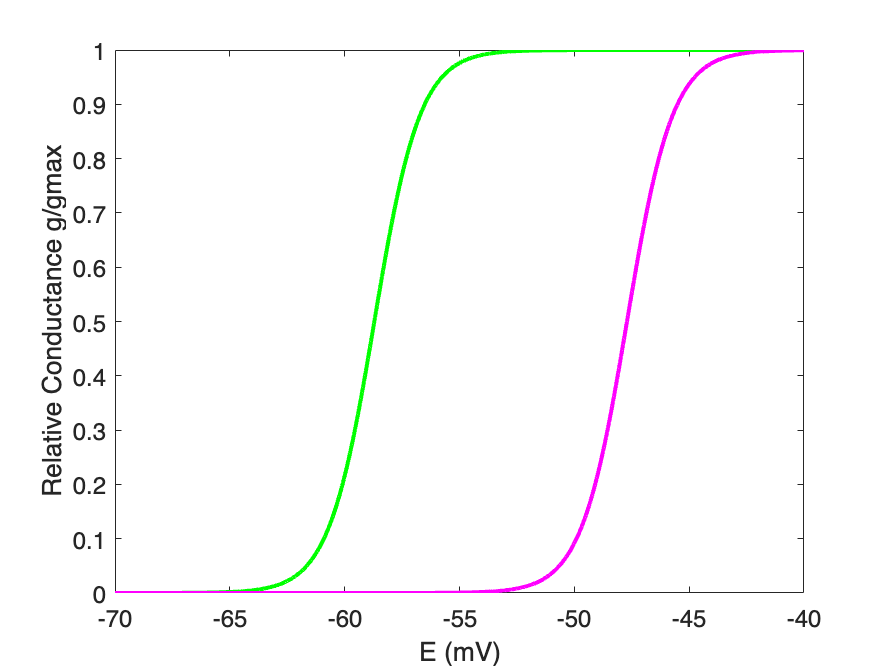


%plotting
figure(2)
hold on %add to figure
box on
xP = E; yP = g_fn; %store values
plot(xP,yP,'m','linewidth',2) %magenta line
xlabel('E (mV)')
ylabel('Relative Conductance g/gmax')
set(gca,'fontsize',12)